# Smooth Electricity Data

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

usage = table2array(readtable("../data/electricityData.xlsx", "Sheet", "usage", "NumHeaderLines", 0));
dates = table2array(readtable("../data/electricityData.xlsx", "Sheet", "dates", "NumHeaderLines", 0));
sectors = table2array(readtable("../data/electricityData.xlsx", "Sheet", "sectors", "ReadVariableNames", false));
whos

  Name           Size            Bytes  Class       Attributes

  dates        315x1              2542  datetime              
  sectors        1x4               488  cell                  
  usage        315x4             10080  double                



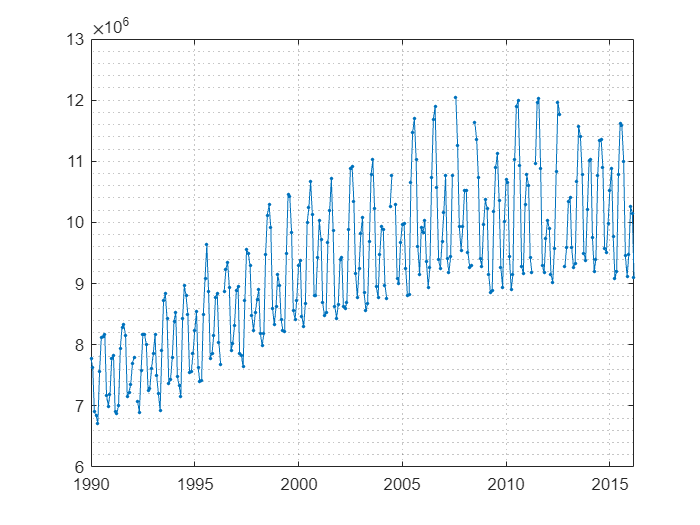

total = usage(:, end);
sectorUsage = usage(:, 1:3);
sectors = sectors(1:3);
plot(dates, total, ".-")
grid minor

## Task 1

tot12 = smoothdata(total, "movmean", 12)

tot12 = 1.0e+07 *

    0.7236
    0.7361
    0.7458
    0.7537
    0.7501
    0.7455
    0.7433
    0.7434
    0.7451
    0.7451


hold on
plot(dates, tot12, ".-")
tot24 = smoothdata(total, "movmean", 24)

tot24 = 1.0e+07 *

    0.7433
    0.7460
    0.7486
    0.7447
    0.7412
    0.7388
    0.7418
    0.7464
    0.7507
    0.7538


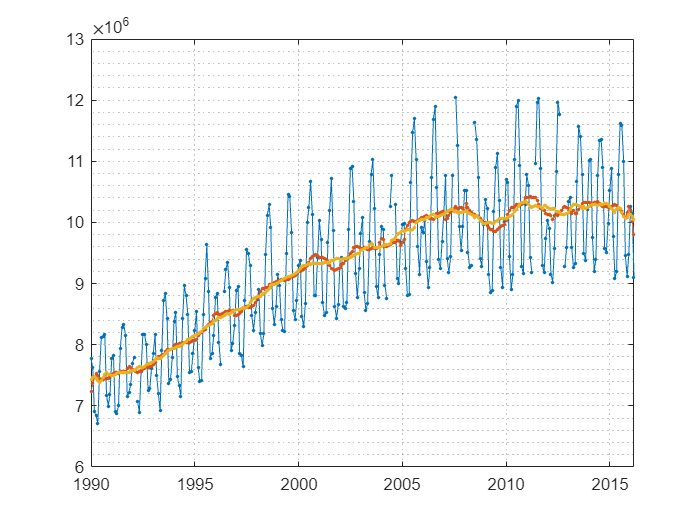

plot(dates, tot24, ".-")
hold off

## Task 2

sectorUsage24 = smoothdata(sectorUsage, "movmean", 24)

sectorUsage24 = 1.0e+06 *

    2.5315    2.0576    2.5893
    2.5697    2.0565    2.5785
    2.5888    2.0591    2.5831
    2.5751    2.0469    2.5711
    2.5514    2.0381    2.5683
    2.5289    2.0348    2.5699
    2.5289    2.0477    2.5771
    2.5579    2.0620    2.5804
    2.5811    2.0756    2.5875
    2.5930    2.0871    2.5950


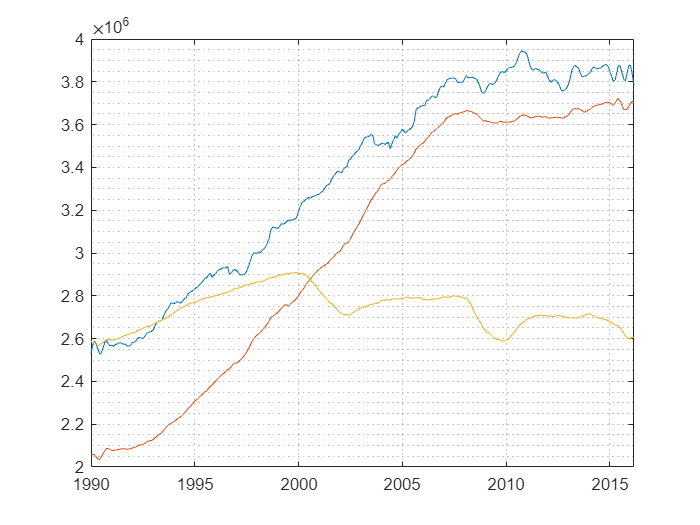

plot(dates, sectorUsage24)
grid minor